# Transmitter

## Simulation variables

SNRdB = 30;                % SNR in dB (Usused ATM)

totalNoSlots = 3;          % Number slots containing information simulated

perfectEstimation = false; % Perfect synchronization and channel estimation (Unused ATM)
rng("default");            % Set default random number generator for repeatability

fileID = fopen('Bits.bin','r'); %send bit file
fileID2 = fopen('RecBits.bin','w'); %recieve bit file

## Set 5G  variables

 [carrier, pdsch, NHARQProcesses, rvSeq, codeRate, encodeDLSCH, decodeDLSCH] = genvar5g

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: true
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: true
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


NHARQProcesses = 1

rvSeq = 0

codeRate = 0.4785

encodeDLSCH =   nrDLSCH with properties:

    MultipleHARQProcesses: true
           TargetCodeRate: 0.4785
        LimitedBufferSize: 25344


decodeDLSCH =   nrDLSCHDecoder with properties:

        MultipleHARQProcesses: true
               TargetCodeRate: 0.4785
         TransportBlockLength: 5120
            LimitedBufferSize: 25344
        LDPCDecodingAlgorithm: 'Normalized min-sum'
                ScalingFactor: 0.7500
    MaximumLDPCIterationCount: 6


## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel config

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-C";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;


constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements

% Initial timing offset
offset = 0;

longwave = 0.00001+0.00001i;

srec = 1;
erec = 15371;


estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TransmitterEntity(carrier, pdsch, encodeDLSCH, harqEntity, nSlot, newPrecodingWeight, codeRate, fileID, nTxAnts, decodeDLSCH);


    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
    

    longwave = cat(1, longwave,txWaveform);
end




## Pluto Send

%% Transmit waveform over the air
plutoTx = sdrtx('Pluto', RadioID='usb:0');
plutoTx.CenterFrequency = 2400000000;
plutoTx.Gain = 0;
plutoTx.BasebandSampleRate = channel.SampleRate

plutoTx =   comm.SDRTxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 2.4000e+09
                      Gain: 0
            ChannelMapping: 1
        BasebandSampleRate: 15360000
    ShowAdvancedProperties: false

  Show all properties


plutoTx.ShowAdvancedProperties = true;
plutoTx.FrequencyCorrection = 0;

%% Reciever waveform over the air

rxPluto = sdrrx('Pluto', RadioID='usb:0');
rxPluto.CenterFrequency = 2400000000;
rxPluto.GainSource = "AGC Fast Attack";
rxPluto.BasebandSampleRate = channel.SampleRate

rxPluto =   comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 2.4000e+09
                GainSource: 'AGC Fast Attack'
            ChannelMapping: 1
        BasebandSampleRate: 15360000
            OutputDataType: 'int16'
           SamplesPerFrame: 20000
           EnableBurstMode: false
    ShowAdvancedProperties: false

  Show all properties


rxPluto.OutputDataType = 'double';
rxPluto.SamplesPerFrame = 16700000;
rxPluto.ShowAdvancedProperties = true;
rxPluto.FrequencyCorrection = 0;

% Transmit waveform (for 10 sec):
%%transmitRepeat(plutoTx, longwave)
% Transmit waveform (for 10 sec):
%%longwave2 = capture(rxPluto, 46114)



% Transmitting data
step(plutoTx,longwave);

## Establishing connection to hardware. This process can take several seconds.


% Receiving data
[data, len] = step(rxPluto);

## Establishing connection to hardware. This process can take several seconds.





% Stop transmission:
pause(10)
release(rxPluto);
fprintf('Recieving stopped.\n')

Recieving stopped.


release(plutoTx);
fprintf('Transmission stopped.\n')

Transmission stopped.


## Decode

Slot 0. HARQ Proc 0: CW0: Initial transmission failed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   0
   0
   1
   1
   0
   1
   0
   1
   0
   1


Slot 1. HARQ Proc 0: CW0: Initial transmission failed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   0
   0
   1
   1
   0
   1
   0
   1


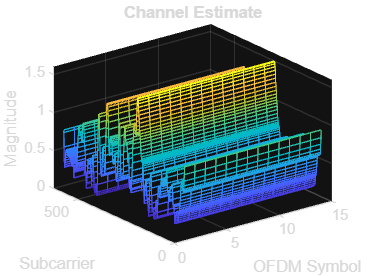

Slot 2. HARQ Proc 0: CW0: Initial transmission failed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   0
   0
   1
   1
   1
   1
   0
   0
   0
   1


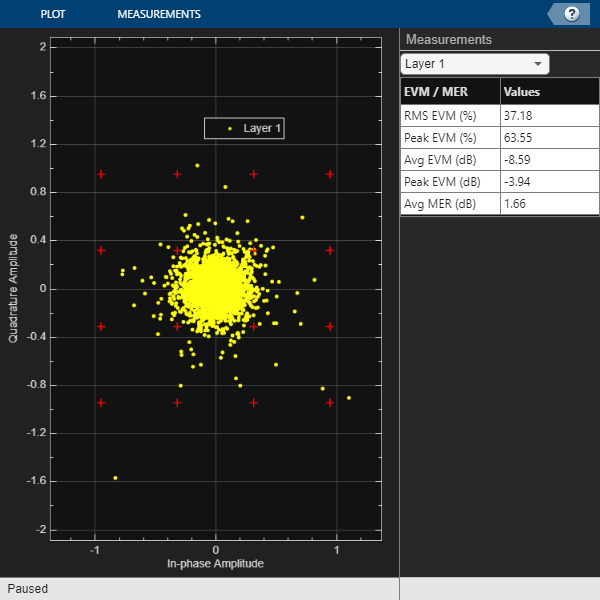

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

     recWave = data(srec:erec,1);

     srec = srec + 15371;
     erec = erec + 15371;
   
    [decbits, statusReport, pdschEq] = RecieverEntity(carrier, pdsch, decodeDLSCH, harqEntity, recWave, offset, fileID2, newPrecodingWeight, trBlkSizes);
    disp("Slot "+(nSlot)+". "+statusReport);
    decbits

    constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq));

end 

## Local Functions

function noise = generateAWGN(SNRdB,nRxAnts,Nfft,sizeRxWaveform)
% Generate AWGN for a given value of SNR in dB (SNRDB), which is the
% receiver SNR per RE and antenna, assuming the channel does
% not affect the power of the signal. NRXANTS is the number of receive
% antennas. NFFT is the FFT size used in OFDM demodulation. SIZERXWAVEFORM
% is the size of the receive waveform used to calculate the size of the
% noise matrix.

    % Normalize noise power by the IFFT size used in OFDM modulation, as
    % the OFDM modulator applies this normalization to the transmitted
    % waveform. Also normalize by the number of receive antennas, as the
    % channel model applies this normalization to the received waveform by
    % default. The SNR is defined per RE for each receive antenna (TS
    % 38.101-4).
    SNR = 10^(SNRdB/10); % Calculate linear noise gain
    N0 = 1/sqrt(2.0*nRxAnts*double(Nfft)*SNR);
    noise = N0*complex(randn(sizeRxWaveform),randn(sizeRxWaveform));
end
    
function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end

function estChannelGrid = precodeChannelEstimate(estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate.

    % Linearize 4-D matrix and reshape after multiplication
    K = size(estChannelGrid,1);
    L = size(estChannelGrid,2);
    R = size(estChannelGrid,3);
    estChannelGrid = reshape(estChannelGrid,K*L*R,[]);
    estChannelGrid = estChannelGrid*W;
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end
